# **PRE-OPERATOIRE**

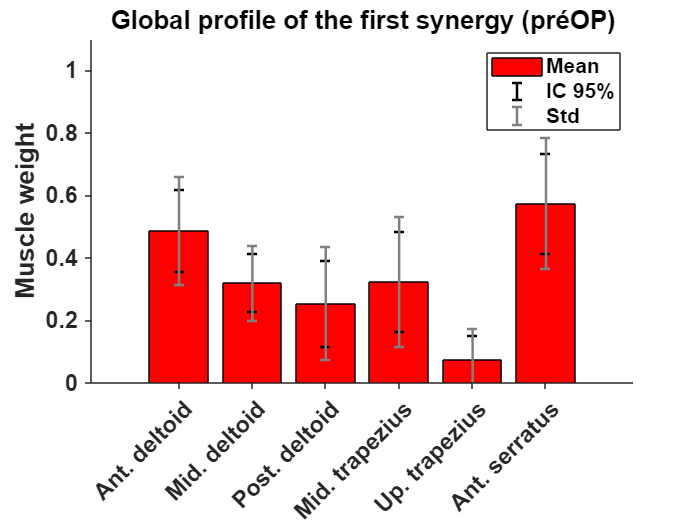

% SYNERGIES 
W = Profilglobalsynergiespr;

noms_muscles = {'Ant. deltoid', 'Mid. deltoid', 'Post. deltoid', ...
                'Mid. trapezius', 'Up. trapezius', 'Ant. serratus'};

% Initialiser des matrices pour stocker les synergies
synergy1 = zeros(6, 9); % 6 muscles, 9 sujets
synergy2 = zeros(6, 9);

% Séparer les colonnes en synergie 1 et 2
for i = 1:9
    synergy1(:, i) = W(:, (i-1)*2 + 1);  % colonnes impaires (1,3,...)
    synergy2(:, i) = W(:, (i-1)*2 + 2);  % colonnes paires (2,4,...)
end

% Calcul des moyennes, écart-types, erreurs standard et IC
n = 9;
t_val = tinv(0.975, n-1); % valeur t pour IC à 95% et n-1 degrés de liberté

mean_synergy1 = mean(synergy1, 2);
std_synergy1 = std(synergy1, 0, 2);
sem_synergy1 = std_synergy1 / sqrt(n);
IC_synergy1 = t_val * sem_synergy1;

mean_synergy2 = mean(synergy2, 2);
std_synergy2 = std(synergy2, 0, 2);
sem_synergy2 = std_synergy2 / sqrt(n);
IC_synergy2 = t_val * sem_synergy2;


% Synergie 1
figure;
x = 1:6;
bar(mean_synergy1, 'r')
hold on
errorbar(x, mean_synergy1, IC_synergy1, 'k', 'LineStyle', 'none', 'LineWidth', 1.5) % IC
errorbar(x, mean_synergy1, std_synergy1, 'Color', [0.5 0.5 0.5], 'LineStyle', 'none', 'LineWidth', 1.5) % STD
title('Global profile of the first synergy (préOP)', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Muscle weight');
xticks(1:6)
xticklabels(noms_muscles)
xtickangle(45)
ylim([0 1.1])
set(gca, 'XTick', 1:6, ...
         'XTickLabel', noms_muscles, ...
         'FontSize', 14, ...
         'FontWeight', 'bold', ...
         'TickDir', 'out', ...
         'Box', 'off');
legend('Mean', 'IC 95%', 'Std', 'Location', 'northeast')
hold off

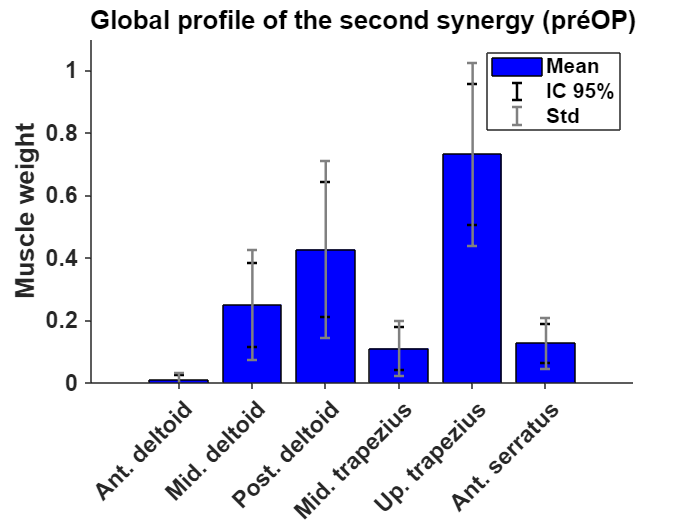


% Synergie 2
figure;
x = 1:6;
bar(mean_synergy2, 'b')
hold on
errorbar(x, mean_synergy2, IC_synergy2, 'k', 'LineStyle', 'none', 'LineWidth', 1.5) % IC
errorbar(x, mean_synergy2, std_synergy2, 'Color', [0.5 0.5 0.5], 'LineStyle', 'none', 'LineWidth', 1.5) % STD
title('Global profile of the second synergy (préOP)', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Muscle weight');
xticks(1:6)
xticklabels(noms_muscles)
xtickangle(45)
ylim([0 1.1])
set(gca, 'XTick', 1:6, ...
         'XTickLabel', noms_muscles, ...
         'FontSize', 14, ...
         'FontWeight', 'bold', ...
         'TickDir', 'out', ...
         'Box', 'off');
legend('Mean', 'IC 95%', 'Std', 'Location', 'northeast')
hold off

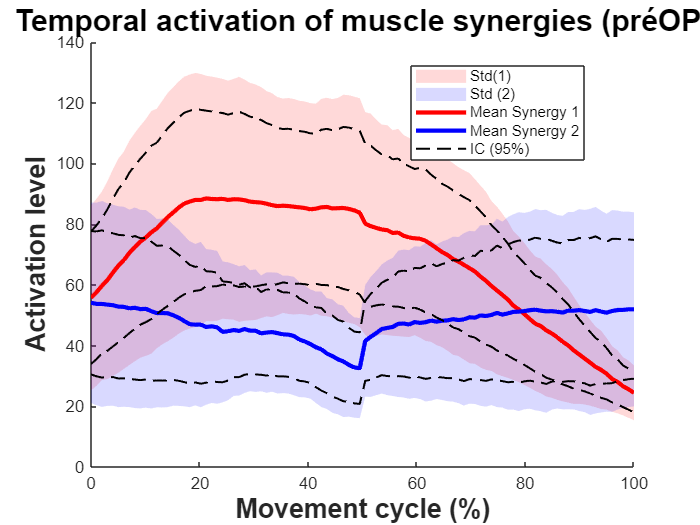

% Activations  
H = Profilglobalactivationspr;

% Initialiser les matrices originales (1000 points, 9 sujets)
activation1_raw = zeros(1000, 9);
activation2_raw = zeros(1000, 9);

for i = 1:9
    activation1_raw(:, i) = H(:, (i-1)*2 + 1);
    activation2_raw(:, i) = H(:, (i-1)*2 + 2);
end

% Interpolation sur 100 points
x_old = linspace(0, 100, 1000);
x_new = linspace(0, 100, 100);

activation1 = zeros(100, 9);
activation2 = zeros(100, 9);

for i = 1:9
    activation1(:, i) = interp1(x_old, activation1_raw(:, i), x_new, 'spline');
    activation2(:, i) = interp1(x_old, activation2_raw(:, i), x_new, 'spline');
end

% Moyenne, écart-type, IC
mean_activation1 = mean(activation1, 2);
std_activation1 = std(activation1, 0, 2);
sem_activation1 = std_activation1 / sqrt(10);
IC_activation1 = tinv(0.975, 9) * sem_activation1;

mean_activation2 = mean(activation2, 2);
std_activation2 = std(activation2, 0, 2);
sem_activation2 = std_activation2 / sqrt(10);
IC_activation2 = tinv(0.975, 9) * sem_activation2;

% Affichage avec incertitude
figure;
hold on

% Zones std
h_std1 = fill([x_new fliplr(x_new)], ...
     [mean_activation1' + std_activation1' fliplr(mean_activation1' - std_activation1')], ...
     'r', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

h_std2 = fill([x_new fliplr(x_new)], ...
     [mean_activation2' + std_activation2' fliplr(mean_activation2' - std_activation2')], ...
     'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

% Courbes moyennes
h_mean1 = plot(x_new, mean_activation1, 'r', 'LineWidth', 2.5);
h_mean2 = plot(x_new, mean_activation2, 'b', 'LineWidth', 2.5);

% IC pointillés noirs
h_ic1 = plot(x_new, mean_activation1 + IC_activation1, '--k', 'LineWidth', 1.2);
plot(x_new, mean_activation1 - IC_activation1, '--k', 'LineWidth', 1.2);
plot(x_new, mean_activation2 + IC_activation2, '--k', 'LineWidth', 1.2);
plot(x_new, mean_activation2 - IC_activation2, '--k', 'LineWidth', 1.2);

% Mise en forme
xlabel('Movement cycle (%)', 'FontSize', 16, 'FontWeight', 'bold');
ylabel('Activation level', 'FontSize', 16, 'FontWeight', 'bold');
title('Temporal activation of muscle synergies (préOP)', 'FontSize', 18, 'FontWeight', 'bold');

% Légende propre
legend([h_std1, h_std2, h_mean1, h_mean2, h_ic1], ...
       {'Std(1)', 'Std (2)', ...
        'Mean Synergy 1', 'Mean Synergy 2', ...
        'IC (95%)'}, ...
       'Location', 'best');

Comparasion avec cinématique élévation HT 

% === Données EMG (activations) === 
H = Profilglobalactivationspr;

activation1_raw = zeros(1000, 9);
activation2_raw = zeros(1000, 9);

for i = 1:9
    activation1_raw(:, i) = H(:, (i-1)*2 + 1);
    activation2_raw(:, i) = H(:, (i-1)*2 + 2);
end

% Interpolation
x_old = linspace(0, 100, 1000);
x_new = linspace(0, 100, 100);

activation1 = zeros(100, 9);
activation2 = zeros(100, 9);
for i = 1:9
    activation1(:, i) = interp1(x_old, activation1_raw(:, i), x_new, 'spline');
    activation2(:, i) = interp1(x_old, activation2_raw(:, i), x_new, 'spline');
end

% Moyennes et IC
mean_activation1 = mean(activation1, 2);
std_activation1 = std(activation1, 0, 2);
IC_activation1 = tinv(0.975, 9) * std_activation1 / sqrt(10);

mean_activation2 = mean(activation2, 2);
std_activation2 = std(activation2, 0, 2);
IC_activation2 = tinv(0.975, 9) * std_activation2 / sqrt(10);

% === Données cinématiques : Élévation HT combinée (droite + gauche) ===
load('all_angles_statistics_Pre_operatoire.mat');

right_mean = all_data.combined.right.HT.Elevation_globale.mean_deg;
left_mean = all_data.combined.left.HT.Elevation_globale.mean_deg;
mean_HT = (right_mean + left_mean) / 2;

right_std = all_data.combined.right.HT.Elevation_globale.std_deg;
left_std = all_data.combined.left.HT.Elevation_globale.std_deg;
std_HT = (right_std + left_std) / 2;

% === Affichage combiné sur un seul axe (gauche) ===
figure;
hold on;
title('Activation synergies + Élévation HT (avec écart-type)', 'FontSize', 18, 'FontWeight', 'bold');

% Tout sur l’axe gauche
yyaxis left
set(gca, 'YColor', 'k', 'FontSize', 14, 'FontWeight', 'bold');

% Zone verte claire : ± std HT
fill([x_new fliplr(x_new)], ...
     [mean_HT' + std_HT' fliplr(mean_HT' - std_HT')], ...
     'g', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

% Moyenne HT
plot(x_new, mean_HT, 'g-.', 'LineWidth', 2.5);

% Zones std activations
fill([x_new fliplr(x_new)], ...
     [mean_activation1' + std_activation1' fliplr(mean_activation1' - std_activation1')], ...
     'r', 'FaceAlpha', 0.15, 'EdgeColor', 'none');
fill([x_new fliplr(x_new)], ...
     [mean_activation2' + std_activation2' fliplr(mean_activation2' - std_activation2')], ...
     'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none');

% Moyennes activations
plot(x_new, mean_activation1, 'r-', 'LineWidth', 2.5);
plot(x_new, mean_activation2, 'b-', 'LineWidth', 2.5);

% Axes et légende
xlabel('Movement Cycle (%)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Amplitude (°)', 'FontSize', 14); 
legend({'HT Std', 'HT Mean', ...
        'Synergy 1 Std', 'Synergy 2 Std', ...
        'Synergy 1 Mean', 'Synergy 2 Mean', ...
        'Location', 'best'});

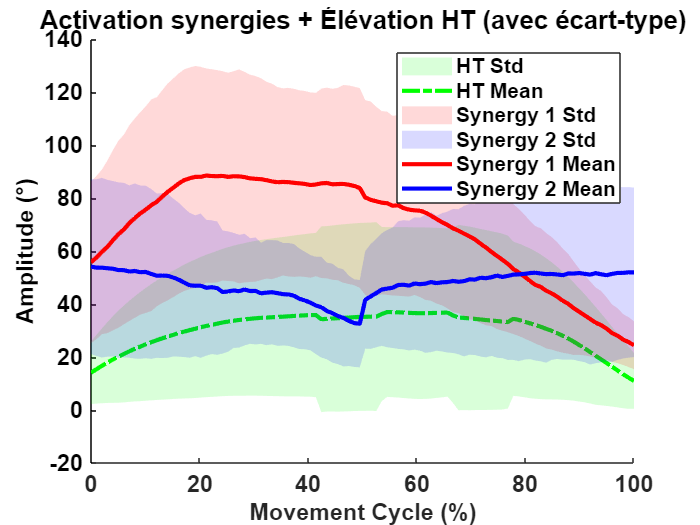


% Supprimer l’axe droit
yyaxis right
set(gca, 'YColor', 'none'); % masque l'axe
ylabel(''); % supprime l’étiquette